Homework #06

## 1a

i)

A=[-2, -4, 0; 4, -0, 0; 0, -8, 0; -2, -20, 0];
b=[-1; -3; -1; -3];

disp('attempt to solve with least sqs:')

attempt to solve with least sqs:


x=inv(A.'*A)*(A.'*b)

x =    NaN
   NaN
   NaN


We get NaNs.

This is because the system is formally overdetermined (the equations are contradictory), so the rank is less than N (where [M,N]=size(A)). So A^T*A, an NxN matrix, is non-invertible.

disp('(A^T * A)^-1:')

(A^T * A)^-1:


disp(inv(A.'*A))

   Inf   Inf   Inf
   Inf   Inf   Inf
   Inf   Inf   Inf



But this method requires inverting (A^T*A) so we can't use it.

ii)

disp('A^T * A:')

A^T * A:


disp(A.'*A)

    24    48     0
    48   480     0
     0     0     0



disp('A^T * b:')

A^T * b:


disp(A.'*b)

    -4
    72
     0




one_sol=pinv(A)*b

one_sol =    -0.5833
    0.2083
         0


second_sol=[one_sol(1,1); one_sol(2,1); 99]

second_sol =    -0.5833
    0.2083
   99.0000


1iii)

Assumptions: 1) Minimizes the error, but also 2) require that the solution’s norm is as small as possible. This is necessary to have 1 unique solution since A^T * A * x = A^T * b already has infinite solutions (z can vary).

x_unique=pinv(A)*b

x_unique =    -0.5833
    0.2083
         0


iv)

disp('from Matlab:')

from Matlab:


x_matlab=A\b;

disp(x_matlab)

   -0.5833
    0.2083
         0



disp('norm of x from Matlab:')

norm of x from Matlab:


disp(norm(x_matlab))

    0.6194



disp('x calculated from pseudoinverse:')

x calculated from pseudoinverse:


disp(x_unique)

   -0.5833
    0.2083
         0



disp('norm of x from pseudoinverse:')

norm of x from pseudoinverse:


disp(norm(x_unique))

    0.6194



They are the same.

## 1b

A=[3, 6, 1;
    6, 12, 2];
b=[-5;
    -4];

i) The rank of A is 1 because the second equation is the first equation x 2; A is formally underdetermined and r<M.

An x that exactly solves this cannot be found because it has two contradictory equations (same equation from A and two distinct b entries).

ii) Assumptions: 1) Minimizes the error, but also 2) require that the solution’s norm is as small as possible. This is necessary to have 1 unique solution since A^T * A * x = A^T * b already has infinite solutions:

disp('A^T * A:')

A^T * A:


disp(A.'*A)

    45    90    15
    90   180    30
    15    30     5



disp('A^T * b:')

A^T * b:


disp(A.'*b)

   -39
   -78
   -13



(all the same equation)

Calculation:

x_unique=pinv(A)*b

x_unique =    -0.1696
   -0.3391
   -0.0565


## 2

2a)

So for our least sqs solution, we want to minimize the distance between Ax and b,$|Ax-b|^2$, which is = $(Ax-b)^T(Ax-b)$

So we have an optimization problem and want to look for where the derivative = 0:


$$\frac{d}{dx}(Ax-b)^T(Ax-b)$$



$$=\frac{d}{dx}(x^TA^TAx-b^TAx-x^TA^Tb+b^Tb)$$



$$=2(A^TAx-A^Tb)=0
$$


Therefore, $A^TAx=A^Tb$ and $x=(A^TA)^{-1}(A^Tb)$

A=[-4, -1, -1;
    8, -10, 0;
    2, 5, -2;
    -7, 0, -7;
    -7, 1, -3];
b=[-7; -3; -6; -2; -9];

x=inv(A.'*A)*(A.'*b)

x =     0.0904
    0.1189
    0.8745


2b)

v1 = A(:,1);
v2 = A(:,2);
v3 = A(:,3);

y1_hat=v1 / norm(v1);

y2=v2 - ((v2.'*y1_hat).*y1_hat);

y2_hat = y2 / norm(y2);

y3=v3 - ((v3.'*y1_hat).*y1_hat) - ((v3.'*y2_hat).*y2_hat);

y3_hat = y3 / norm(y3);

Q=[y1_hat y2_hat y3_hat]

Q =    -0.2965   -0.2635    0.1672
    0.5930   -0.6870   -0.3389
    0.1482    0.5870   -0.6440
   -0.5189   -0.2840   -0.6651
   -0.5189   -0.1829   -0.0018


R=Q.'*A

R =    13.4907   -5.4111    5.1887
   -0.0000    9.8853    1.6263
    0.0000   -0.0000    5.7820


2c)

[Can I use Matlab to directly multiply]

x_qr=(inv(R)*Q.'*b)

x =     0.0904
    0.1189
    0.8745


2d)

They are the same.

## 3

3a)

Both the SVD and Covariance Matrix method give the same answer because using SVD to give U, sigma, and V, we know that U will have as columns the eigenvectors of F*F^T and be normalized ((1/N)*F*F^T). (1/N)*F*F^T is the definition of the covariance matrix, whose eigenvectors will be the PCs.

3b)

F=[-0.8, -14, 2.4, -8.4, 4, -2.4, 6, 4, 8.8;
-7.2, 22, -8.8, 15, -8, 6.4, -8, -2, -8.8;
26, 3.2, 14, -2.4, 4, -7.2, -6, -14, -18];
[M, N] = size(F);

F_centered = F;
F_means = mean(F, 2);
F_centered(1,:) = F_centered(1,:) - F_means(1,1);
F_centered(2,:) = F_centered(2,:) - F_means(2,1);
F_centered(3,:) = F_centered(3,:) - F_means(3,1);

% using SVD
[U_svd, sigma, V] = svd(F_centered);
disp('Principal Components from SVD:')

Principal Components from SVD:


for i = 1:1:length(U_svd)
    disp(U_svd(:, i))
end

    0.2300
   -0.0611
   -0.9713

   -0.4828
    0.8594
   -0.1684

    0.8450
    0.5076
    0.1682



disp('Expansion Matrix:')

Expansion Matrix:


T_svd=sigma*V.'

T_svd =   -25.0258   -7.7016  -12.5368   -0.5467   -2.5050    6.0211    7.6677   14.6111   20.0159
  -10.2662   25.0405  -11.1653   17.2642   -9.5662    7.7851   -8.8477   -1.3785   -8.8661
    0.0526   -0.1133   -0.0735    0.1237    0.0030    0.0211    0.0113    0.0217   -0.0467



% using covariance matrix
C=(1/N).*F_centered * F_centered.';
[U_cov, lambda]=eig(C);
disp('Principal Components from Covariance Matrix:')

Principal Components from Covariance Matrix:


for i = 1:1:length(U_cov)
    disp(U_cov(:, i))
end

   -0.8450
   -0.5076
   -0.1682

   -0.4828
    0.8594
   -0.1684

   -0.2300
    0.0611
    0.9713



disp('Expansion Matrix:')

Expansion Matrix:


T_cov=U_cov.' * F_centered

T_cov =    -0.0526    0.1133    0.0735   -0.1237   -0.0030   -0.0211   -0.0113   -0.0217    0.0467
  -10.2662   25.0405  -11.1653   17.2642   -9.5662    7.7851   -8.8477   -1.3785   -8.8661
   25.0258    7.7016   12.5368    0.5467    2.5050   -6.0211   -7.6677  -14.6111  -20.0159


They are the same PCs (different directions but along same eigenvectors) for both methods. Likewise, same expansion matrices, although the order of the rows depends on the order of the PCs. 

3c) grades for different courses for different students: So student 1 [describe]

3d)

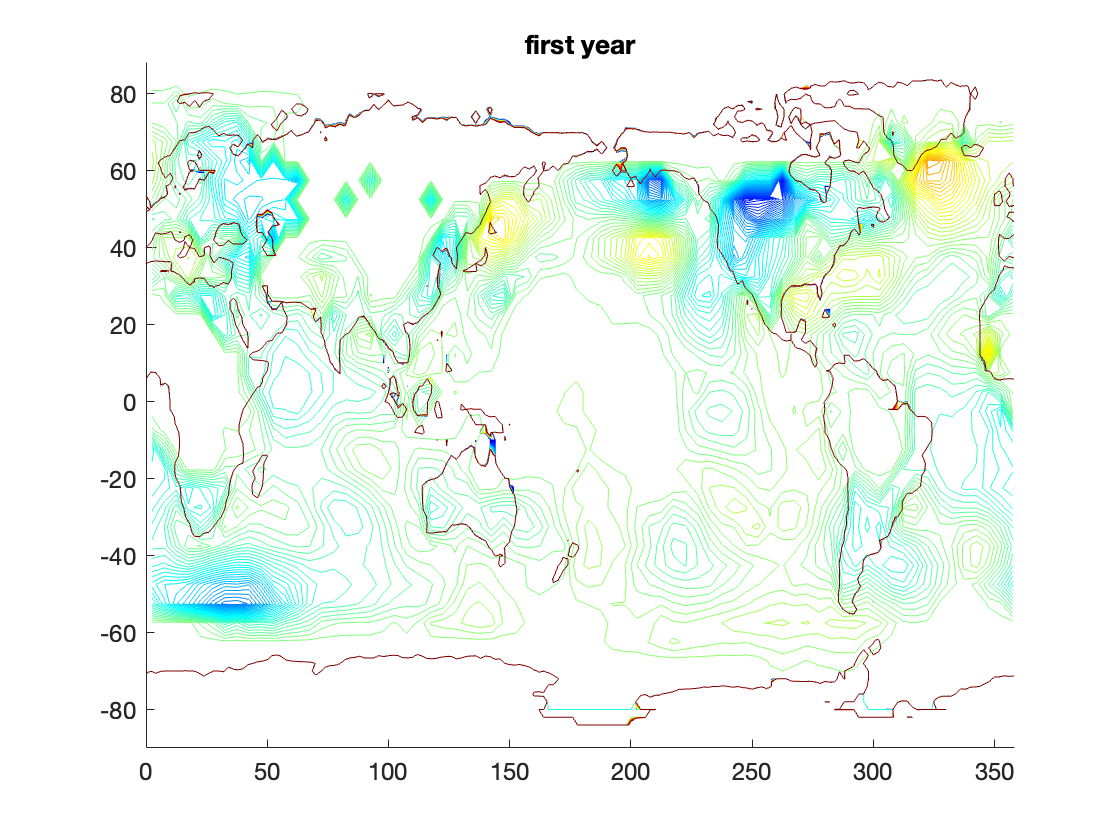

load global_temperature.mat
% lat 1x36, lon 1x72, T1 72x36x138, years 1x138
load global_topography.mat
% topo 180x90, X 180x1, Y 90x1

figure; hold on; colormap(jet)
title('first year')
TMP=permute(squeeze(T1(:,:,1)),[2,1]);
contour(lon,lat,TMP,linspace(-5,5,100))
TOP=permute(squeeze(topo(:,:,1)),[2,1]);
contour(X,Y,TOP,linspace(-5,5,100))
hold off

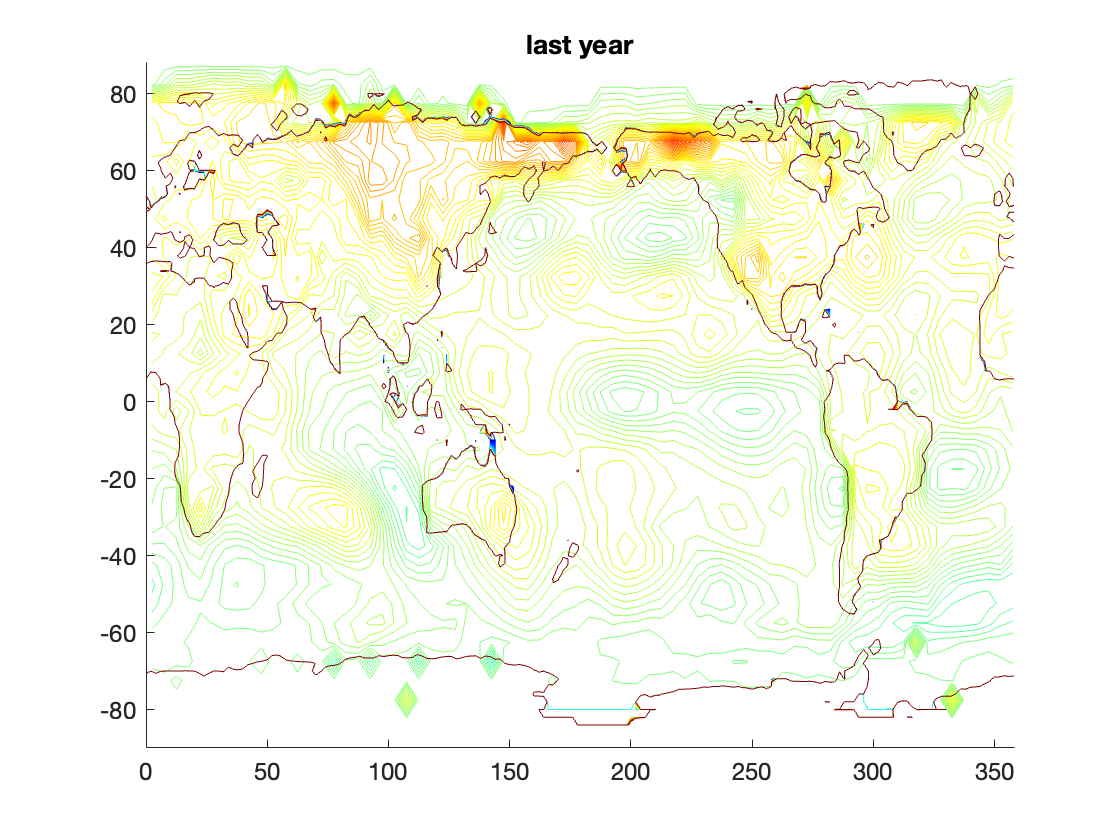


figure; hold on; colormap(jet)
title('last year')
TMP=permute(squeeze(T1(:,:,end)),[2,1]);
contour(lon,lat,TMP,linspace(-5,5,100))
TOP=permute(squeeze(topo(:,:,end)),[2,1]);
contour(X,Y,TOP,linspace(-5,5,100))
hold off

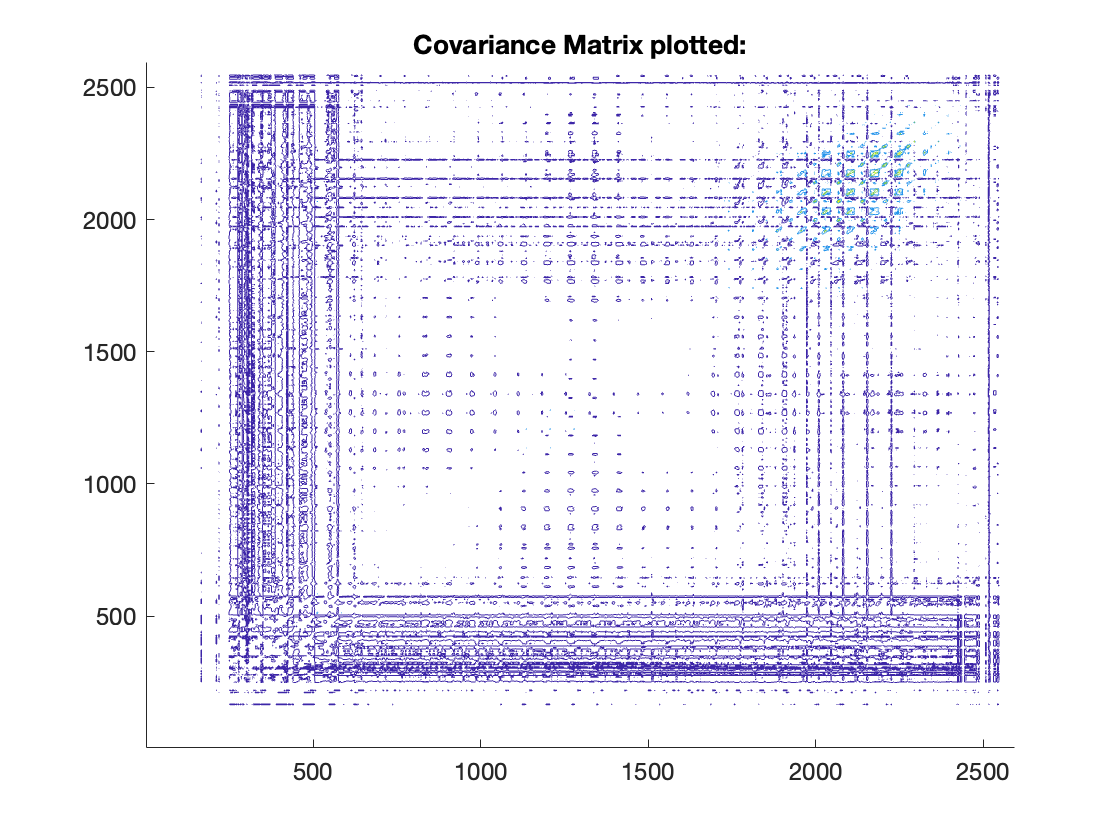

Top 3 PCs



[size1, size2, size3]=size(T1);

N=size1*size2;
T1_reshape = reshape(T1, [N, size3]);

T2 = T1_reshape;
% reshape() will keep third dimension correctly
T_means = mean(T1_reshape, 2);

for i=1:1:N
    T2(i,:) = T2(i,:) - T_means(i,1);
end

T_cov = (1/size3).* T2 * T2.';
figure; hold on
title('Covariance Matrix plotted:')
contour(T_cov)
hold off

Top 3 PCs:

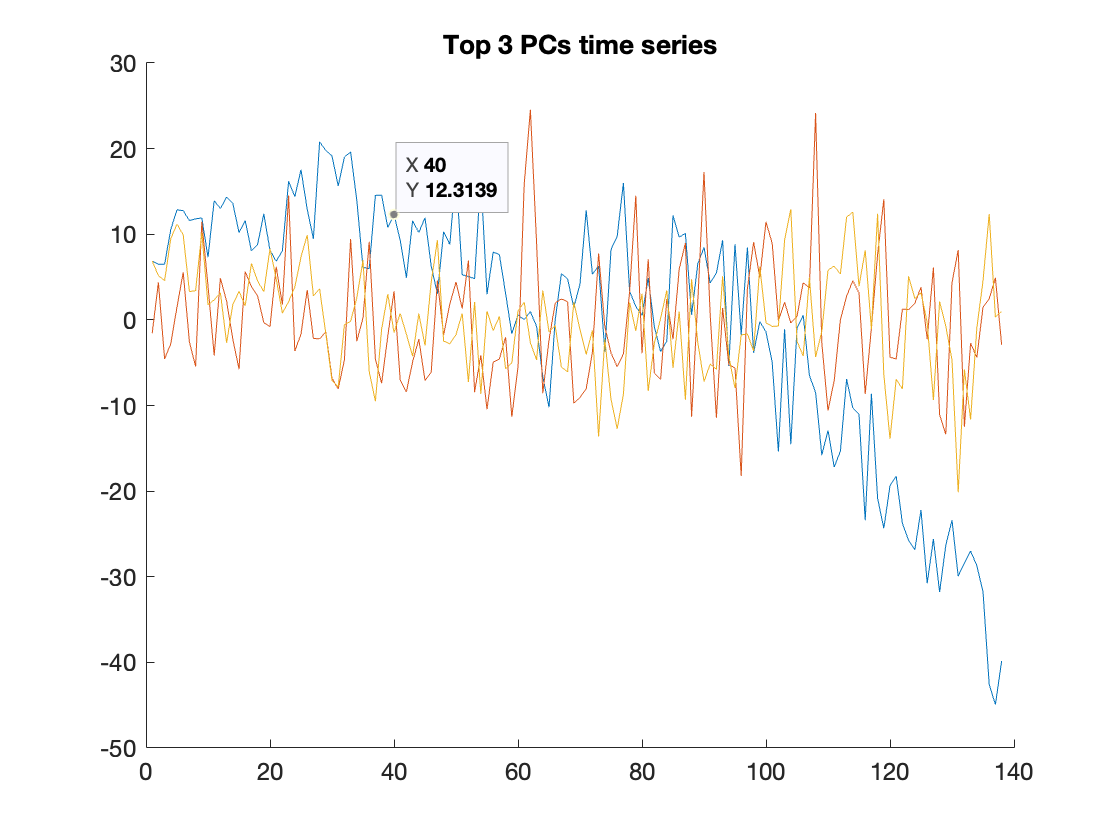

[T_U, T_lambda]=eig(T_cov);
% eig() will go from greatest lambda to smallest
pc1=T_U(:, 1);
pc2=T_U(:, 2);
pc3=T_U(:, 3);

T_T = T_U.' * T2;
figure; hold on;
title('Top 3 PCs time series')
for i = 1:1:3
    plot(1:size3, T_T(i, :))
end
hold off

[interpret time series results graph]

## 4

X=[ 0.1, 2.8, 3.5, 0.5, 1.2, 4, 2.1, 0, 2.9, 3.6, 0.4, 1.1;
3.8, 1.4, 0.5, 3.3, 2.7, 0, 1.7, 4.1, 1.1, 0.5, 3.5, 2.9;
9.7, -1.3, -4.2, 8.1, 5.3, -5.8, 1.8, 9.9, -1.5, -4.2, 8.2, 5.5;
9.9, -1.7, -4.3, 8.5, 5.7, -5.8, 2.3, 9.7, -1.5, -4.3, 8.3, 5.5];
Y=[-7.6, -3.6, -2.8, -6.9, -6.1, -2.2, -4.9, -7.4, -3.9, -2.7, -7, -6.1;
-2.1, -6.5, -7.4, -2.9, -3.8, -8.1, -5.1, -2.4, -6.3, -7.5, -2.8, -3.8;
-2.7, -6, -6.9, -3.1, -4, -7.3, -5, -2.7, -6, -6.9, -3.1, -4];

4a)